% CIV102 Bridge Design Project
% design iteration 1 
% flange height
% got rid of bottom
% increased 
clear; close all;

% Step 0: Initialize Parameters
L = 1200;   % Length of the bridge
n = 1200;   % Discretize into 1 mm segments
P = 400;    % Total weight of the train [N]
x = linspace(0, L, n+1);    % x-axis

% Step 1: SFD, BMD Under Train Loading
x_train = [52, 228, 392, 568, 732, 908]; % train load locations
P_train = [1 1 1 1 1 1] * (P/6);

n_train = 345;    % number of train start locations
SFDi = zeros(n_train, n+1);     % 1 SFD for each train start location
BMDi = zeros(n_train, n+1);     % 1 BMD for each train start location

for i = 1:n_train
    x_start_loc = i-52;  % start location of the train, acts like an adjustment factor
    x_train_adj = x_train + x_start_loc;  % adjusted train load locations

    % sum of moments at A equation, rearranged for R_y
    R_y = (sum(P_train .* x_train_adj)) / L;

    % sum of F_y equation, rearranged for L_y
    L_y = sum(P_train) - R_y;

    v = L_y; % initial shear force at left support
    SFDi(i, 1:x_train_adj(1)) = v; % filling in a shear force value for a given range of x-values
    v = v - P_train(1); % updating the shear force
    SFDi(i, x_train_adj(1):x_train_adj(2)) = v; % filling in the updated value for a given range of x-values
    v = v - P_train(2);
    SFDi(i, x_train_adj(2):x_train_adj(3)) = v;
    v = v - P_train(3);
    SFDi(i, x_train_adj(3):x_train_adj(4)) = v;
    v = v - P_train(4);
    SFDi(i, x_train_adj(4):x_train_adj(5)) = v;
    v = v - P_train(5);
    SFDi(i, x_train_adj(5):x_train_adj(6)) = v;
    v = v - P_train(6);
    SFDi(i, x_train_adj(6):n) = v;
    v = v + R_y;    % final shear force update at the right support
    SFDi(i, n+1) = v;
    
    BMDi(i,:) = cumtrapz(SFDi(i,:));   % integrating SFDi to get BMD
end

SFD = max(abs(SFDi));   % the absolute maximum values of shear force at all locations
BMD = max(BMDi);        % the maximum value of all bending moments at all locations
disp(BMDi(n+1))

  606.0000



disp (BMD)

   1.0e+04 *

         0    0.0256    0.0512    0.0767    0.1021    0.1275    0.1528    0.1780    0.2032    0.2283    0.2533    0.2783    0.3032    0.3280    0.3528    0.3775    0.4021    0.4267    0.4512    0.4756    0.5000    0.5243    0.5485    0.5727    0.5968    0.6208    0.6448    0.6687    0.6925    0.7163    0.7400    0.7636    0.7872    0.8107    0.8341    0.8575    0.8808    0.9040    0.9272    0.9503    0.9733    0.9963    1.0192    1.0420    1.0648    1.0875    1.1101    1.1327    1.1552    1.1776    1.2000    1.2223    1.2445    1.2667    1.2888    1.3108    1.3328    1.3547    1.3765    1.3983    1.4200    1.4416    1.4632    1.4847    1.5061    1.5275    1.5488    1.5700    1.5912    1.6123    1.6333    1.6543    1.6752    1.6960    1.7168    1.7375    1.7581    1.7787    1.7992    1.8196    1.8400    1.8603    1.8805    1.9007    1.9208    1.9408    1.9608    1.9807    2.0005    2.0203    2.0400    2.0596    2.0792    2.0987    2.1181    2.1375    2.1568    2.1760    2.

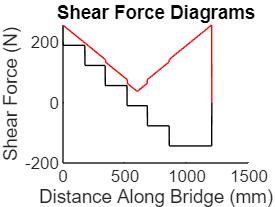

% Plotting the SFD and BMD
figure(1)
hold on
plot(x, SFDi(2,:), "k")
% plot(x, SFDi, 'k')  % SFD for individual location tests
plot(x, SFD, "r")   % SFD for maximum shear force
title("Shear Force Diagrams")
xlabel('Distance Along Bridge (mm)')
ylabel('Shear Force (N)')
hold off

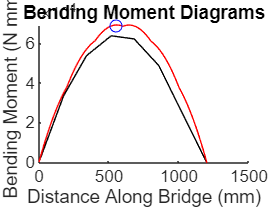


figure(2)
hold on
plot(x, BMDi(1,:), "k")
% plot(x, BMDi, "k")  % BMD for individual location tests
plot(x, BMD, "r")   % BMD for maximum bending moment
title("Bending Moment Diagrams")
xlabel('Distance Along Bridge (mm)')
ylabel('Bending Moment (N mm)')
[~, max_moment_idx] = max(BMD);  % find index of max moment
plot(max_moment_idx, BMD(max_moment_idx), "bo") % plot max moment
hold off


% <COMPLETE> 3. Calculate Sectional Properties
% WORKS Calculate the centroidal axis of i rectangles
base = [120, 1.27, 1.27, 10, 10, 80];
height = [1.27, 80, 80, 1.27, 1.27, 1.27];
area = base.*height;
y_i = [80.635, 40, 40, 74.365, 74.365, 0.635];
y_i_area_sum = sum(area.*y_i);
y_bar = y_i_area_sum / sum(area) % location of centroidal axis from the bottom

y_bar = 46.3534

height_total = 81.27; % INPUT
y_bot = y_bar

y_bot = 46.3534

disp(y_bar)

   46.3534



y_top = height_total - y_bar % INPUT

y_top = 34.9166


% WORKS Calculate the second moment of area, I
I_own = sum((base.*(height.^3))/12);
d = abs(y_bar - y_i);
I_par = sum(area.*(d.^2));
I = I_own + I_par

I = 5.2801e+05


% WORKS Q at centroidal axes
d_i = [(22.54*2) (45.7184)]; % INPUT distance from centroidal axis to centroid of each area ABOVE OR BELOW (whichever easier) centroidal axis as ARRAY
A_i = [(1.27*45.08) (1.27*77.46)]; % INPUT area of rectangles ABOVE OR BELOW centroidal axis (whichever is easier)
Q_cent = sum(A_i.*d_i)

Q_cent = 7.0784e+03


% WORKS Q at glue location
d_glue = 33.0146; % distance from centroid of area of interest to centroid of entire cross-section
area_glue = 152.4; % area(s) that will slip and fall if the glue fails, can be one or many
Q_glue = area_glue*d_glue

Q_glue = 5.0314e+03


% <COMPLETE>   4. Calculate Applied Stress
V = SFD;
b_glue = 22.54; % INPUT area over which glue is spread, may be 2t
b_cent = 2*1.27; % INPUT aka t, thickness at axis of interest

fuck = max(BMD)

fuck = 6.9160e+04

fuckernum2 = max(SFD)

fuckernum2 = 257.3333

sigma_top = (fuck*y_top)/I

sigma_top = 4.5735

sigma_bot = (fuck*y_bot)/I

sigma_bot = 6.0715

tau_cent = (fuckernum2.*Q_cent)./(I*b_cent)

tau_cent = 1.3582

tau_glue = (fuckernum2.*Q_glue)./(I*b_glue)

tau_glue = 0.1088


% <COMPLETE> 5. Material and Thin Plate Buckling Capacities
% To calculate sigma_crit or=tau_crit for thin plate buckling.
% Choose one of four complete equations.
% WORKS Case #1 - 2 restrained, constant stress
k = 4;
E = 4000;
t = 2.54;
b = 82.54; % Change to height of the area of interest
poissons = 0.2;
sigma_buck1= ((k*pi^2*E)/12*(1-(poissons^2)))*((t/b)^2)

sigma_buck1 = 11.9632


% WORKS Case #2 - 1 restrained, constant stress
k = 0.425;
E = 4000;
t = 1.27;
b = 20; % Change to height of the area of interest
poissons = 0.2;
num_2 = (k*pi^2*E);
den_2 = 12*(1 - (poissons^2));
sigma_buck2 = (num_2 / den_2)*(t/b)^2

sigma_buck2 = 5.8728


% WORKS Case #3 - 2 restrained, variable stress
k = 6;
E = 4000;
t = 1.27;
b = 33.6; % Change to height of the area of interest
poissons = 0.2;
num_3 = (k*pi^2*E);
den_3 = 12*(1 - (poissons^2));
sigma_buck3 = (num_3 / den_3)*(t/b)^2

sigma_buck3 = 29.3756


% WORKS Case #4 - 4 restrained, shear stress
k = 5;
E = 4000;
t = 1.27;
poissons = 0.2;
h = 82.54;
a = 46.6;
num_4 = 5*pi^2*E;
den_4 = 12*(1 - (poissons^2));
const_4 = ((t/h)^2) + ((t/a)^2);
sigma_buck4 = (num_4/den_4)*const_4

sigma_buck4 = 16.7832


sigma_tens = ones(1201, 1).*30; % Material props from the handout
sigma_comp = ones(1201, 1).*6;
tau_max = ones(1201, 1).*4;
tau_gluemax = ones(1201, 1).*2; % "Up to 2 if properly cured", if less than 2 days, take value between 0 and 2 
 
%<COMPLETE> 6. FOS
FOS_tens = min(sigma_tens'./ sigma_bot)

FOS_tens = 4.9411

FOS_comp = min(sigma_comp'./ sigma_top)

FOS_comp = 1.3119

FOS_shear = min(tau_max'./tau_cent)

FOS_shear = 2.9451

FOS_glue = min(tau_gluemax'./tau_glue) % 4 is given tau glue, other one is calculated tau (line 137)

FOS_glue = 18.3839

FOS_buck1 = min(sigma_buck1'./ sigma_top)

FOS_buck1 = 2.6158

FOS_buck2 = min(sigma_buck2'./ sigma_top)

FOS_buck2 = 1.2841

FOS_buck3 = min(sigma_buck3'./ sigma_top)

FOS_buck3 = 6.4231

FOS_buckV = min(sigma_buck4'./ tau_cent)

FOS_buckV = 12.3571

FOS = [FOS_tens FOS_comp FOS_shear FOS_glue FOS_buck1 FOS_buck2 FOS_buck3 FOS_buckV]

FOS =     4.9411    1.3119    2.9451   18.3839    2.6158    1.2841    6.4231   12.3571



% <INCOMPLETE> 7. Min FOS and the failure load Pfail
minFOS = min(FOS) % Min of all FOS values

minFOS = 1.2841

P_f = minFOS * P

P_f = 513.6399


% <COMPLETE> 8. Vfail and Mfail
Mf_tens = FOS_tens.*BMD

Mf_tens = 1.0e+05 *

         0    0.0127    0.0253    0.0379    0.0505    0.0630    0.0755    0.0880    0.1004    0.1128    0.1252    0.1375    0.1498    0.1621    0.1743    0.1865    0.1987    0.2108    0.2229    0.2350    0.2471    0.2591    0.2710    0.2830    0.2949    0.3068    0.3186    0.3304    0.3422    0.3539    0.3656    0.3773    0.3890    0.4006    0.4122    0.4237    0.4352    0.4467    0.4581    0.4696    0.4809    0.4923    0.5036    0.5149    0.5261    0.5373    0.5485    0.5597    0.5708    0.5819


Mf_comp = FOS_comp.*BMD

Mf_comp = 1.0e+04 *

         0    0.0336    0.0672    0.1006    0.1340    0.1673    0.2005    0.2336    0.2666    0.2995    0.3324    0.3651    0.3978    0.4304    0.4628    0.4952    0.5276    0.5598    0.5919    0.6240    0.6560    0.6878    0.7196    0.7513    0.7830    0.8145    0.8459    0.8773    0.9085    0.9397    0.9708    1.0018    1.0327    1.0636    1.0943    1.1250    1.1555    1.1860    1.2164    1.2467    1.2769    1.3071    1.3371    1.3671    1.3969    1.4267    1.4564    1.4860    1.5155    1.5450


Vf_shear = FOS_shear.*BMD

Vf_shear = 1.0e+05 *

         0    0.0075    0.0151    0.0226    0.0301    0.0376    0.0450    0.0524    0.0598    0.0672    0.0746    0.0820    0.0893    0.0966    0.1039    0.1112    0.1184    0.1257    0.1329    0.1401    0.1473    0.1544    0.1615    0.1687    0.1758    0.1828    0.1899    0.1969    0.2040    0.2110    0.2179    0.2249    0.2318    0.2388    0.2457    0.2525    0.2594    0.2662    0.2731    0.2799    0.2867    0.2934    0.3002    0.3069    0.3136    0.3203    0.3269    0.3336    0.3402    0.3468


Vf_glue = FOS_glue.*BMD

Vf_glue = 1.0e+06 *

         0    0.0047    0.0094    0.0141    0.0188    0.0234    0.0281    0.0327    0.0374    0.0420    0.0466    0.0512    0.0557    0.0603    0.0649    0.0694    0.0739    0.0784    0.0829    0.0874    0.0919    0.0964    0.1008    0.1053    0.1097    0.1141    0.1185    0.1229    0.1273    0.1317    0.1360    0.1404    0.1447    0.1490    0.1533    0.1576    0.1619    0.1662    0.1705    0.1747    0.1789    0.1832    0.1874    0.1916    0.1958    0.1999    0.2041    0.2082    0.2124    0.2165


Mf_buck1 = FOS_buck1.*BMD

Mf_buck1 = 1.0e+05 *

         0    0.0067    0.0134    0.0201    0.0267    0.0334    0.0400    0.0466    0.0532    0.0597    0.0663    0.0728    0.0793    0.0858    0.0923    0.0987    0.1052    0.1116    0.1180    0.1244    0.1308    0.1371    0.1435    0.1498    0.1561    0.1624    0.1687    0.1749    0.1812    0.1874    0.1936    0.1998    0.2059    0.2121    0.2182    0.2243    0.2304    0.2365    0.2425    0.2486    0.2546    0.2606    0.2666    0.2726    0.2785    0.2845    0.2904    0.2963    0.3022    0.3080


Mf_buck2 = FOS_buck2.*BMD

Mf_buck2 = 1.0e+04 *

         0    0.0329    0.0657    0.0985    0.1311    0.1637    0.1962    0.2286    0.2609    0.2932    0.3253    0.3574    0.3893    0.4212    0.4530    0.4847    0.5164    0.5479    0.5794    0.6108    0.6420    0.6733    0.7044    0.7354    0.7664    0.7972    0.8280    0.8587    0.8893    0.9198    0.9502    0.9806    1.0108    1.0410    1.0711    1.1011    1.1310    1.1609    1.1906    1.2203    1.2499    1.2793    1.3088    1.3381    1.3673    1.3965    1.4255    1.4545    1.4834    1.5122


Mf_buck3 = FOS_buck3.*BMD

Mf_buck3 = 1.0e+05 *

         0    0.0165    0.0329    0.0493    0.0656    0.0819    0.0981    0.1144    0.1305    0.1466    0.1627    0.1788    0.1947    0.2107    0.2266    0.2425    0.2583    0.2741    0.2898    0.3055    0.3212    0.3368    0.3523    0.3678    0.3833    0.3988    0.4142    0.4295    0.4448    0.4601    0.4753    0.4905    0.5056    0.5207    0.5358    0.5508    0.5657    0.5807    0.5955    0.6104    0.6252    0.6399    0.6546    0.6693    0.6839    0.6985    0.7130    0.7275    0.7420    0.7564


Vf_buckV = FOS_buckV.*BMD

Vf_buckV = 1.0e+05 *

         0    0.0317    0.0633    0.0948    0.1262    0.1576    0.1888    0.2200    0.2511    0.2821    0.3130    0.3439    0.3747    0.4054    0.4360    0.4665    0.4969    0.5273    0.5576    0.5877    0.6179    0.6479    0.6778    0.7077    0.7375    0.7672    0.7968    0.8263    0.8558    0.8851    0.9144    0.9436    0.9728    1.0018    1.0307    1.0596    1.0884    1.1171    1.1458    1.1743    1.2028    1.2311    1.2594    1.2877    1.3158    1.3438    1.3718    1.3997    1.4275    1.4552
